# *E.coli (*iJO1366) Tyrosine, Tryptophan, and Phenylalanine Subsystem

Author: H. Scott Hinton, Utah State University

## INTRODUCTION

The purpose of this tutorial is to review the basic structure and capabilities of the Tyrosine,Tryptophan, and Phenylalanine Subsystem of the iJO1366* E.coli* model.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [1,2]. To use this tutorial requires the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://opencobra.github.io/cobratoolbox/latest/index.html.](https://opencobra.github.io/cobratoolbox/latest/index.html.) The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

Initalize the COBRA toolbox.

clear;
initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  (not installed).
 > Checking if remote can be reached ...  (unsuccessful - no internet connection).
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.


 > Try running
   >> TranslateSBML('C:\Users\hinton\cobratoolbox\test\models\Ec_iAF1260_flux1.xml');
   in order to debug.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: C:\gurobi702\win64\matlab
   - [----] TOMLAB_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver int

Select the optimizer solver.

% changeCobraSolver('glpk','all');
changeCobraSolver('gurobi7','all');

 > CBT_LP_SOLVER has been set to gurobi.
 > CBT_MILP_SOLVER has been set to gurobi.
 > CBT_QP_SOLVER has been set to gurobi.
 > CBT_MIQP_SOLVER has been set to gurobi.
 > CBT_NLP_SOLVER has been set to gurobi.


% changeCobraSolver('tomlab_cplex','all');
% changeCobraSolver('gurobi6','all');

Load the *E.coli *iJO1366 model.

load('iJO1366.mat');
saved_model = iJO1366;
model = saved_model;

## PROCEDURE

## **1. **Tyrosine, Tryptophan, and Phenylalanine Metabolism Subsystem

The purpose of this tutorial is to identify and review the structure and capabilities of the "Tyrosine, Tryptophan, and Phenylalanine Metabolism" subsystem of the *E.coli* iJO1366 model. This will begin with an overview of the complete subsystem. This overview will be followed by more detailed descriptions of the individaul L-tyrosine, L-tryptophan, and L-phenylalanine biosynthesis pathways. It will conclude with a simulation that shows the maximum flux that each these amino acids can produce in a range from anaerobic to aerobic conditions.

The reactions associated with the "Tyrosine, Tryptophan, and Phenylalanine Metabolism" subsystem can be extracted from the model as shown below.

model = saved_model;
tyrosineTryptophanPhenylalanineSubSystems = {'Tyrosine, Tryptophan, and Phenylalanine Metabolism'};
tyrosineTryptophanPhenylalanineSubsystemReactions = model.rxns(ismember(model.subSystems,tyrosineTryptophanPhenylalanineSubSystems));
[tmp,tyrosineTryptophanPhenylalanineSubsystem_rxnID] = ismember(tyrosineTryptophanPhenylalanineSubsystemReactions,model.rxns);
reactionNames = model.rxnNames(tyrosineTryptophanPhenylalanineSubsystem_rxnID);
reactionFormulas = printRxnFormula(model,tyrosineTryptophanPhenylalanineSubsystemReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',tyrosineTryptophanPhenylalanineSubsystemReactions)

T = 23×2 table
                                     reactionNames                                              reactionFormulas                    
                ________________________________________________________    ________________________________________________________

    ACANTHAT    'Acetyl-CoA:anthranilate acetyltransferase'                 'accoa_c + anth_c  -> acanth_c + coa_c '                
    ANPRT       'Anthranilate phosphoribosyltransferase'                    'anth_c + prpp_c  -> ppi_c + pran_c '                   
    ANS         'Anthranilate synthase'                                     'chor_c + gln__L_c  -> anth_c + glu__L_c + h_c + pyr_c '
    CHORM       'Chorismate mutase'                                         'chor_c  -> pphn_c '                                    
    CHORS       'Chorismate synth

The map for the "Tyrosine, Tryptophan, and Phenylalanine Metabolism" subsystem created by the Escher visualization tool [3] is shown below.

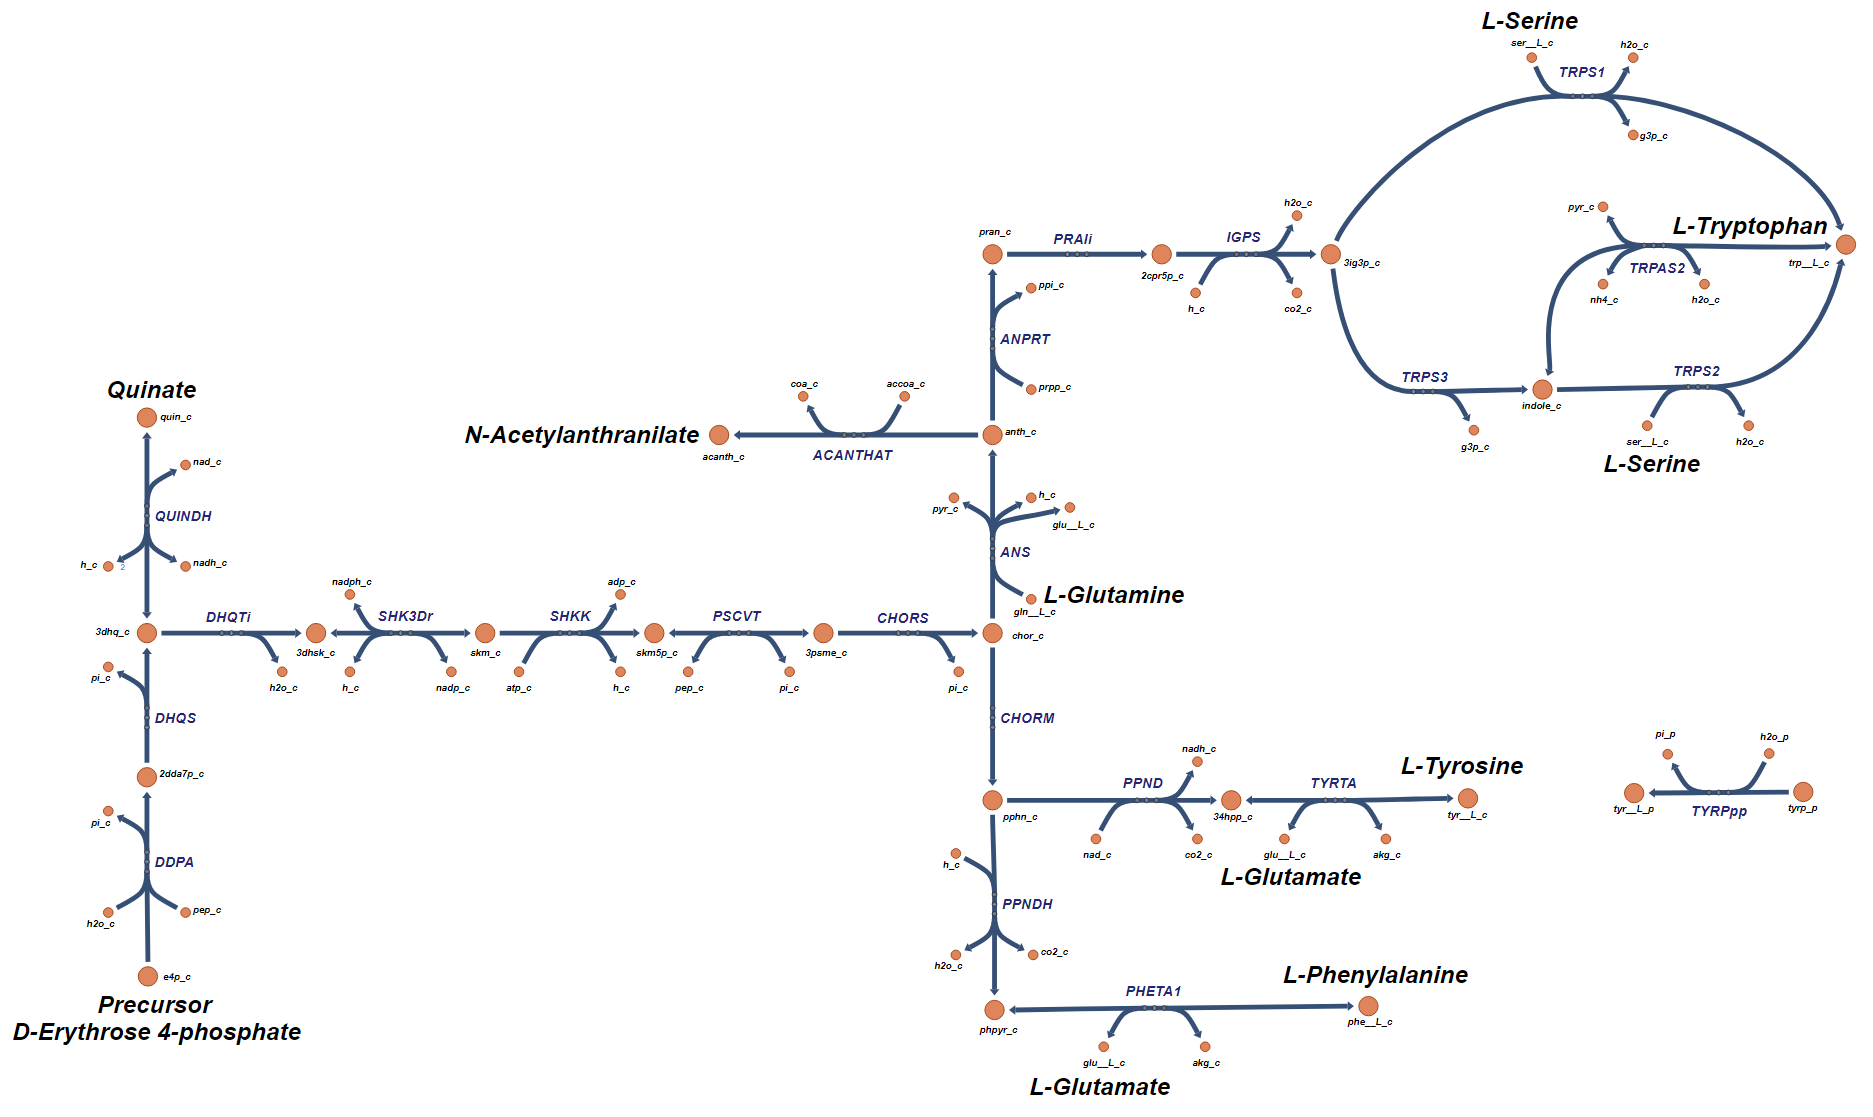

**Figure 1. **The "Tyrosine, Tryptophan, and Phenylalanine Metabolism" subsystem.

As can be seen in this figure, there are two potential pathways that can create the metabolite 'chor_c' which is common to the production of all three amino acids. This pathway as shown in this subsystem begins with either/or D-Erythrose 4-phosphate ('e4p_c') or quinate ('quin_c') and ends with the production of 'chor_c'. The primary pathway, which begins with 'e4p_c',  include the reactions 'DDPA', 'DHQS', 'DHQTi', 'SHK3Dr', 'SHKK', 'PSCVT', 'CHORS'. The second pathway begins with 'quin_c' and includes the reactions   'QUINDH', 'DHQTi', 'SHK3Dr', 'SHKK', 'PSCVT', 'CHORS'. 

The pathway from this intermediate metabolite to L-tryptophan then begins with 'chor_c' and passes through 'ANS (where it adds its amino group through the conversion of L-glutamine to L-glutamate), ANPRT', 'PRAi', and 'IGPS'. The pathway then provides three options; the primary pathway includes 'TRPS3' and 'TRPAS2', alternates include TRPS3' and 'TRPS2' or 'TRPS1'. Both of these alternate pathways will require L-serine to produce L-tryptophan. This pathway of the subsystem also include the dead-end reaction 'ACANTHAT'. The feeding metabolite for this reaction, 'acanth_c', is not produced in the iJO1366 model.

For the production of L-tyrosine begins with 'chor_c' and includes 'CHORM', 'PPND', and 'TYRTA' (provides the amino group from L-glutamate). The subsystem also include the perimplasmic reaction 'TYRPpp' which converts phosphotyrosine ('tyrp_p') to periplasmic L-tyrosine ('tyr__L_p').

Finally, the production of L-phenylalanine ('phe__L_c') begins with 'chor_c' and includes the reactions 'CHORM', 'PPNDH', and 'PHETA1'(provides the amino group from L-glutamate). 

The flux flowing through the primary pathways for each of these amino acids can be mapped onto the Escher [3] map of the subsystem using the file "Aerobic_Reaction_Flux.csv" that contains the flux data for aerobic operation with a maximum glucose uptake rate of -10 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ and an unlimited oxygen uptake rate. 

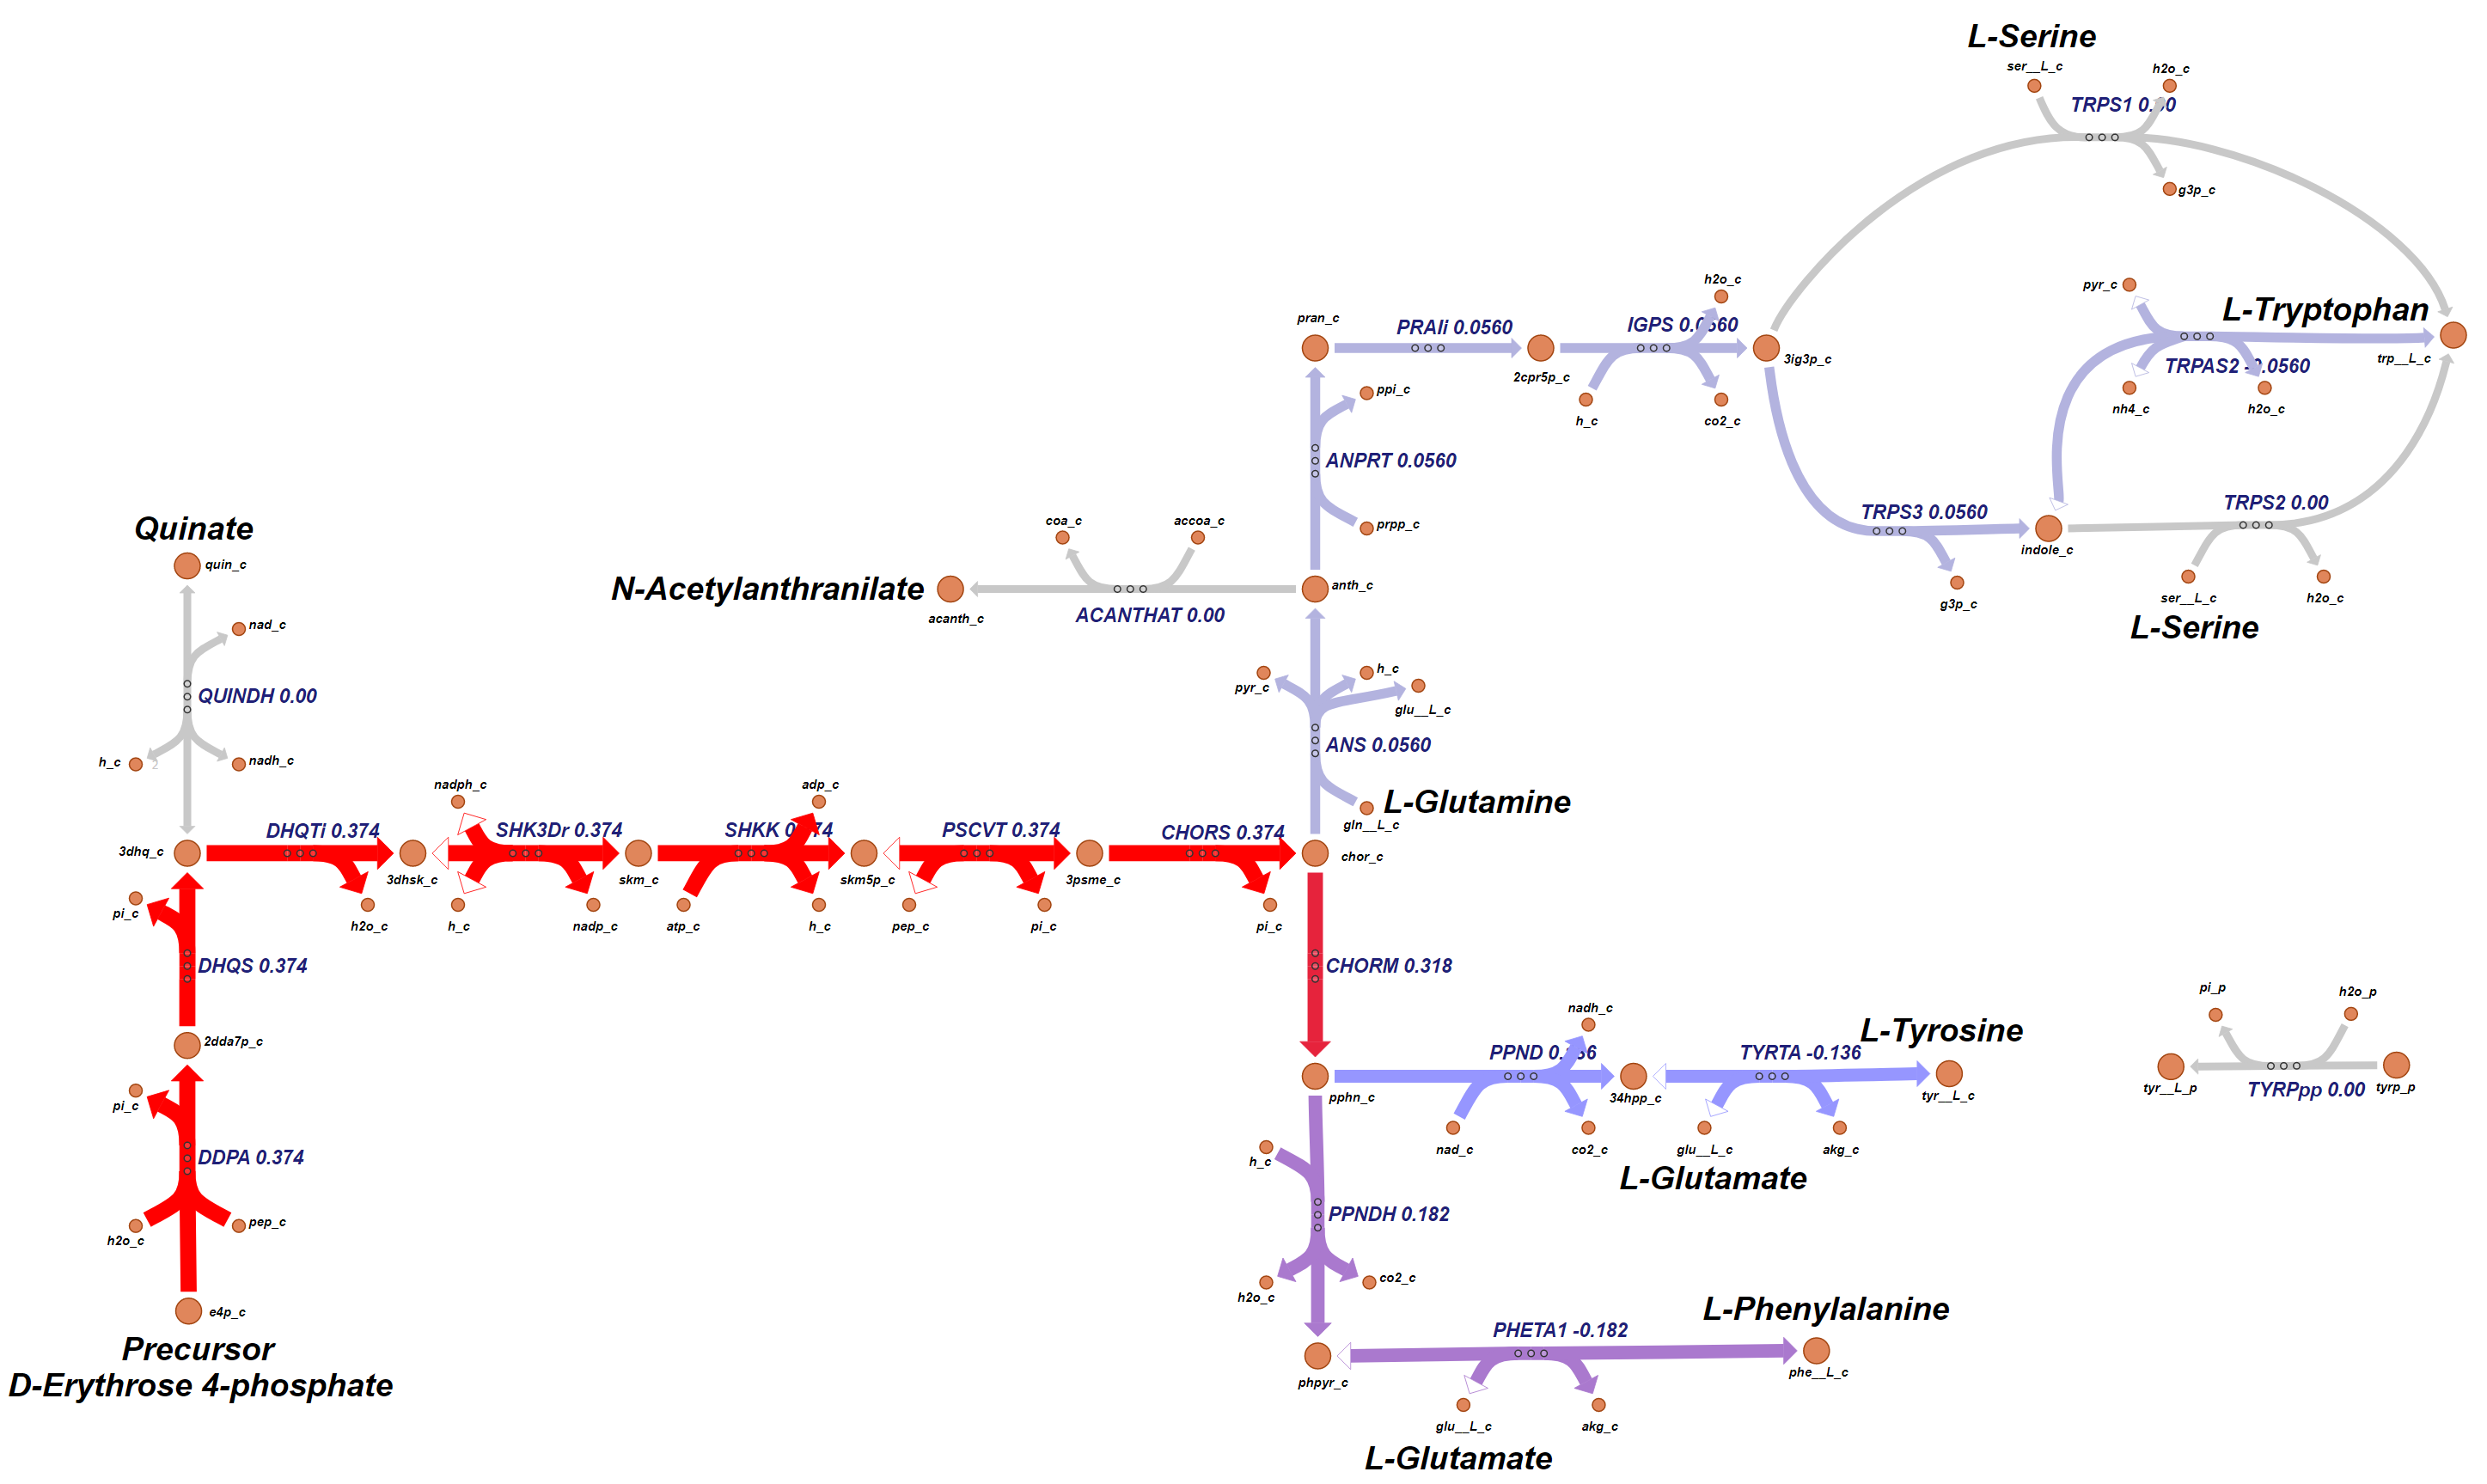

**Figure 2. **The flux flowing through the primary pathways for each of these amino acids can be mapped onto the Escher map of the subsystem using the file "Aerobic_Reaction_Flux.csv" that contains the flux data for aerobic operation with a maximum glucose uptake rate of -10 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ and a maximum oxygen uptake rate of -30 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$.

More detail biosynthesis pathways for each of these amino acids will be described in more detail below.

**2. L-Tyrosine Biosynthesis**

As can be seen in the figure above the primary biosyntheis pathway for the production of L-tyrosine begins with the precursor  D-Erythrose 4-phosphate ('e4p_c') and includes the following reactions 'DDPA', 'DHQS', 'DHQTi', 'SHK3Dr', 'SHKK', 'PSCVT', 'CHORS', 'CHORM', 'PPND', 'TYRTA'. 

 A figure showing all the reactions that can be used to produce L-tyrosine is shown below.

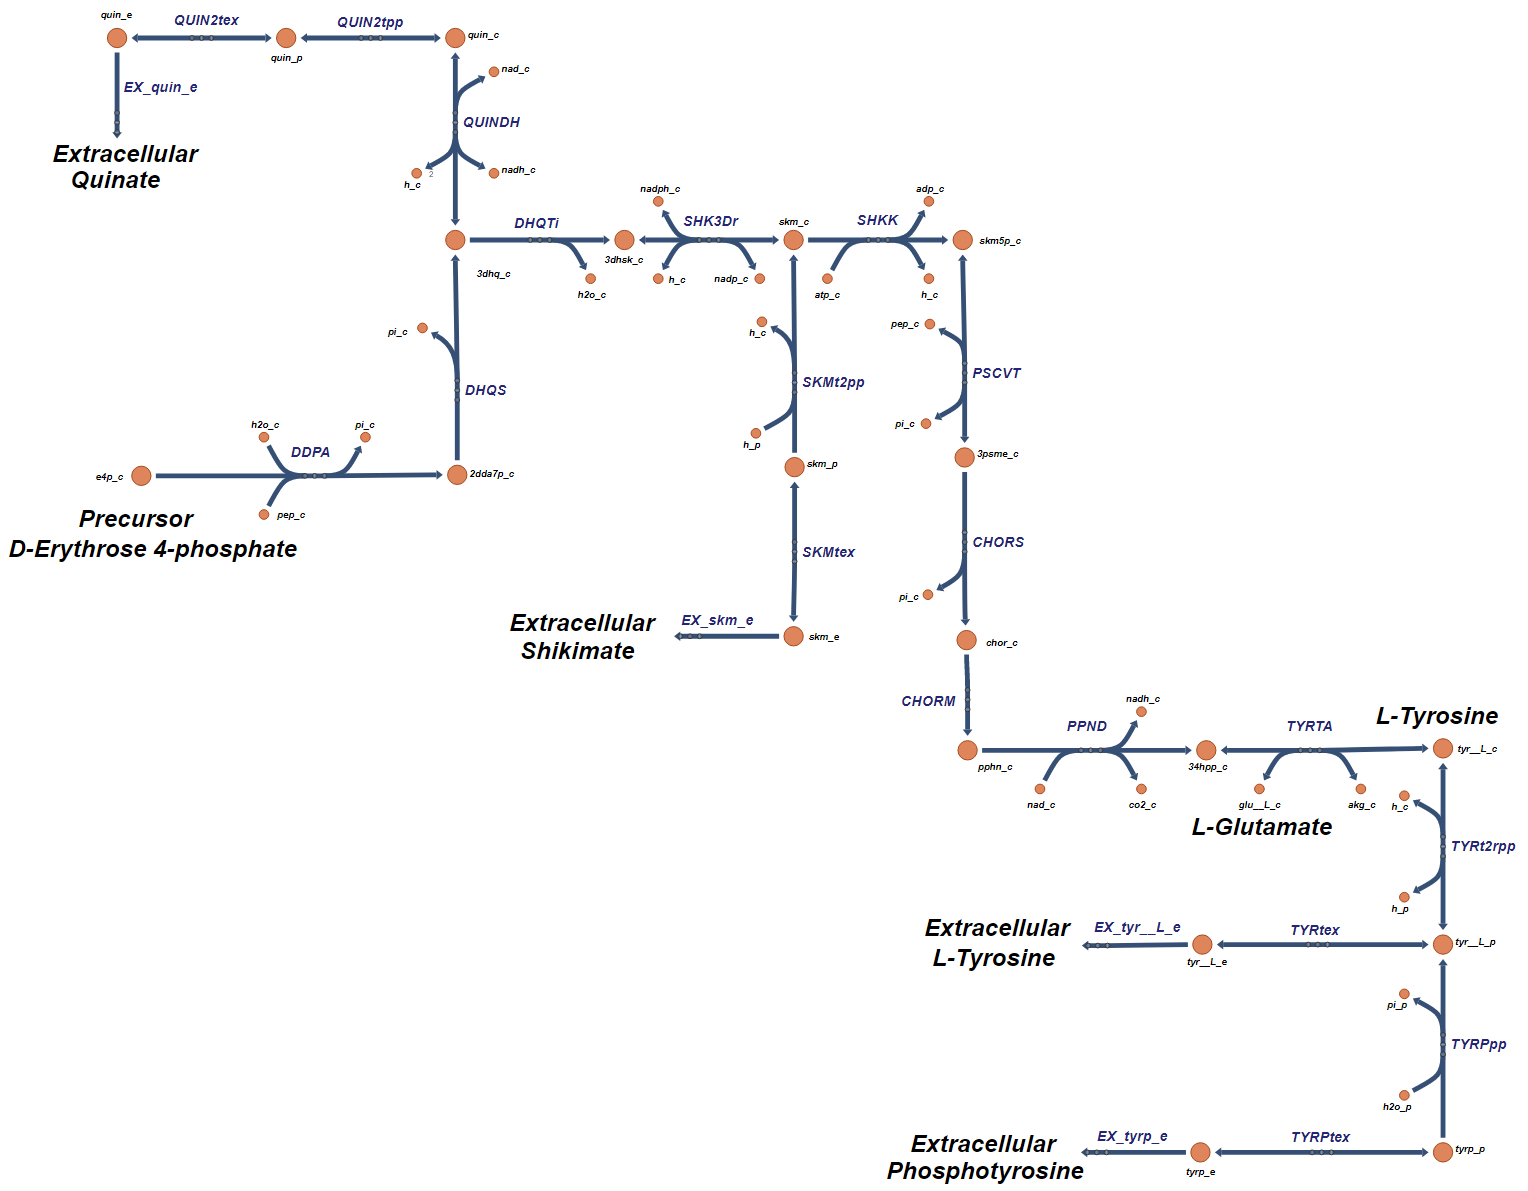

**Figure 3.**  A network map all the reactions and pathways that can be used to produce L-tyrosine.

Note that in addition to the primary pathway ('DDPA', 'DHQS', 'DHQTi', 'SHK3Dr', 'SHKK', 'PSCVT', 'CHORS', 'CHORM', 'PPND', 'TYRTA') there are several other pathways that can lead to the increased production of L-Tyrosine. On the top of the figure there is an alternate pathway ('EX_quin_e', 'QUIN2tex', 'QUIN2tpp', 'QUINDH' ) that begins by the diffusion of quinate ('quin_e') into the periplasm ('quin_p') and then transported into the cytoplasm ('quin_c') where it adds to the pool of 3-Dehydroquinate ('3dhq_c') which is an intermediate step in the biosynthesis of L-tyrosine. Another pathway ('EX_skm_e', 'SKMtex', 'SKMt2pp') that can contribute to the front end of primary pathway involves the diffusion ('skm_e') and tranport of Shikimate ('skm_p'). L-tyrosine can also be added to the cell through the proton powered transporter 'TYR2trpp' which bring perimplasmic L-tyrosine ('tyr__L_p') that is either diffused into the cell via 'TYRtex' or converts diffused ('TYRPtex') phosphotyrosine ('tyrp_p') to L-tyrosine ('tyr__L_p') through 'TYRPpp'.

Now let's explore the flux through this pathway under aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
tyrosineReactions = transpose({'DDPA','DHQS','DHQTi','SHK3Dr','SHKK','PSCVT','CHORS','CHORM','PPND','TYRTA',...
    'QUINDH','QUIN2tpp','QUIN2tex','TYRt2rpp','TYRtex','TYRPpp','TYRPtex'});
[tmp,tyrosine_rxnID] = ismember(tyrosineReactions,model.rxns);
printLabeledData(tyrosineReactions, round(FBAsolution.x(tyrosine_rxnID),3))

DDPA	0.374	
DHQS	0.374	
DHQTi	0.374	
SHK3Dr	0.374	
SHKK	0.374	
PSCVT	0.374	
CHORS	0.374	
CHORM	0.318	
PPND	0.136	
TYRTA	-0.136	
QUINDH	0	
QUIN2tpp	0	
QUIN2tex	0	
TYRt2rpp	0	
TYRtex	0	
TYRPpp	0	
TYRPtex	0	


In this simple case on the primary pathway supports active flux.

When a cell is producing a recombinant protein, it might be required to produce additional L-tyrosine for the desired bioproduct.  What is the maximum amount of L-tyrosine that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'tyr__L_c');

DM_tyr__L_c	tyr__L_c 	->	


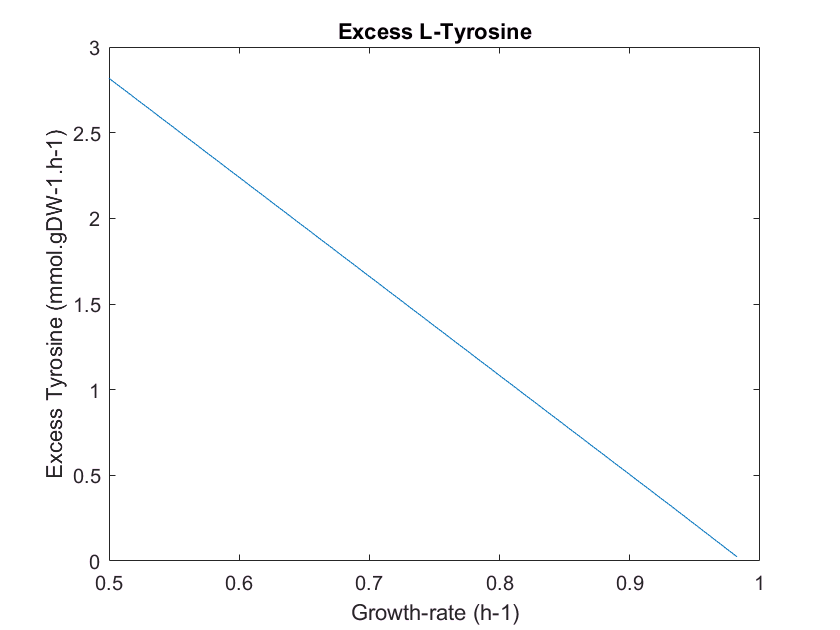

[tmp,tyrosine_MAX_rxnID] = ismember({'DM_tyr__L_c'},model.rxns);
model = changeObjective(model,'DM_tyr__L_c'); % Set the objective function
FBAsolution_tyrosine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
% printLabeledData({'DM_tyr__L_c'}, round(FBAsolution_tyrosine.x(tyrosine_MAX_rxnID),3))
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessTyrosine = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_tyrosine = optimizeCbModel(model,'max'); % Perform FBA
    excessTyrosine(i) = FBAsolution_tyrosine.f;
    growthRate(i) = x;
    x = x + xInc;
end
% growthRate = 0:20;
figure(1);
plot(growthRate,excessTyrosine)
title('Excess L-Tyrosine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess Tyrosine (mmol.gDW-1.h-1)');

**Figure 4. **The maximum amount of excess L-tyrosine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-tyrosine increases the growth-rate will need to decrease. In this figure we can see that the excess L-tyrosine flux can increase from 0.02426 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 2.817 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-tyrosine flux beyond these levels will require uinsg the pathways that allow for the trasnport of L-tyrosine from the extracellular media. 

**3. L-Tryptophan Biosynthesis**

As can be seen in the figure above the primary biosyntheis pathway for the production of L-tryptophan begins with the precursor  'e4p_c' and includes the following reactions 'DDPA', 'DHQS', 'DHQTi', 'SHK3Dr', 'SHKK', 'PSCVT', 'CHORS', 'ANS', 'ANPRT', 'PRAIi', 'IGPS', 'TRPS1', 'TRPS2', 'TRPS3', 'TRPAS2', and 'QUINDH'. A figure showing all the reactions that can be used to produce L-tryptophan is shown below.

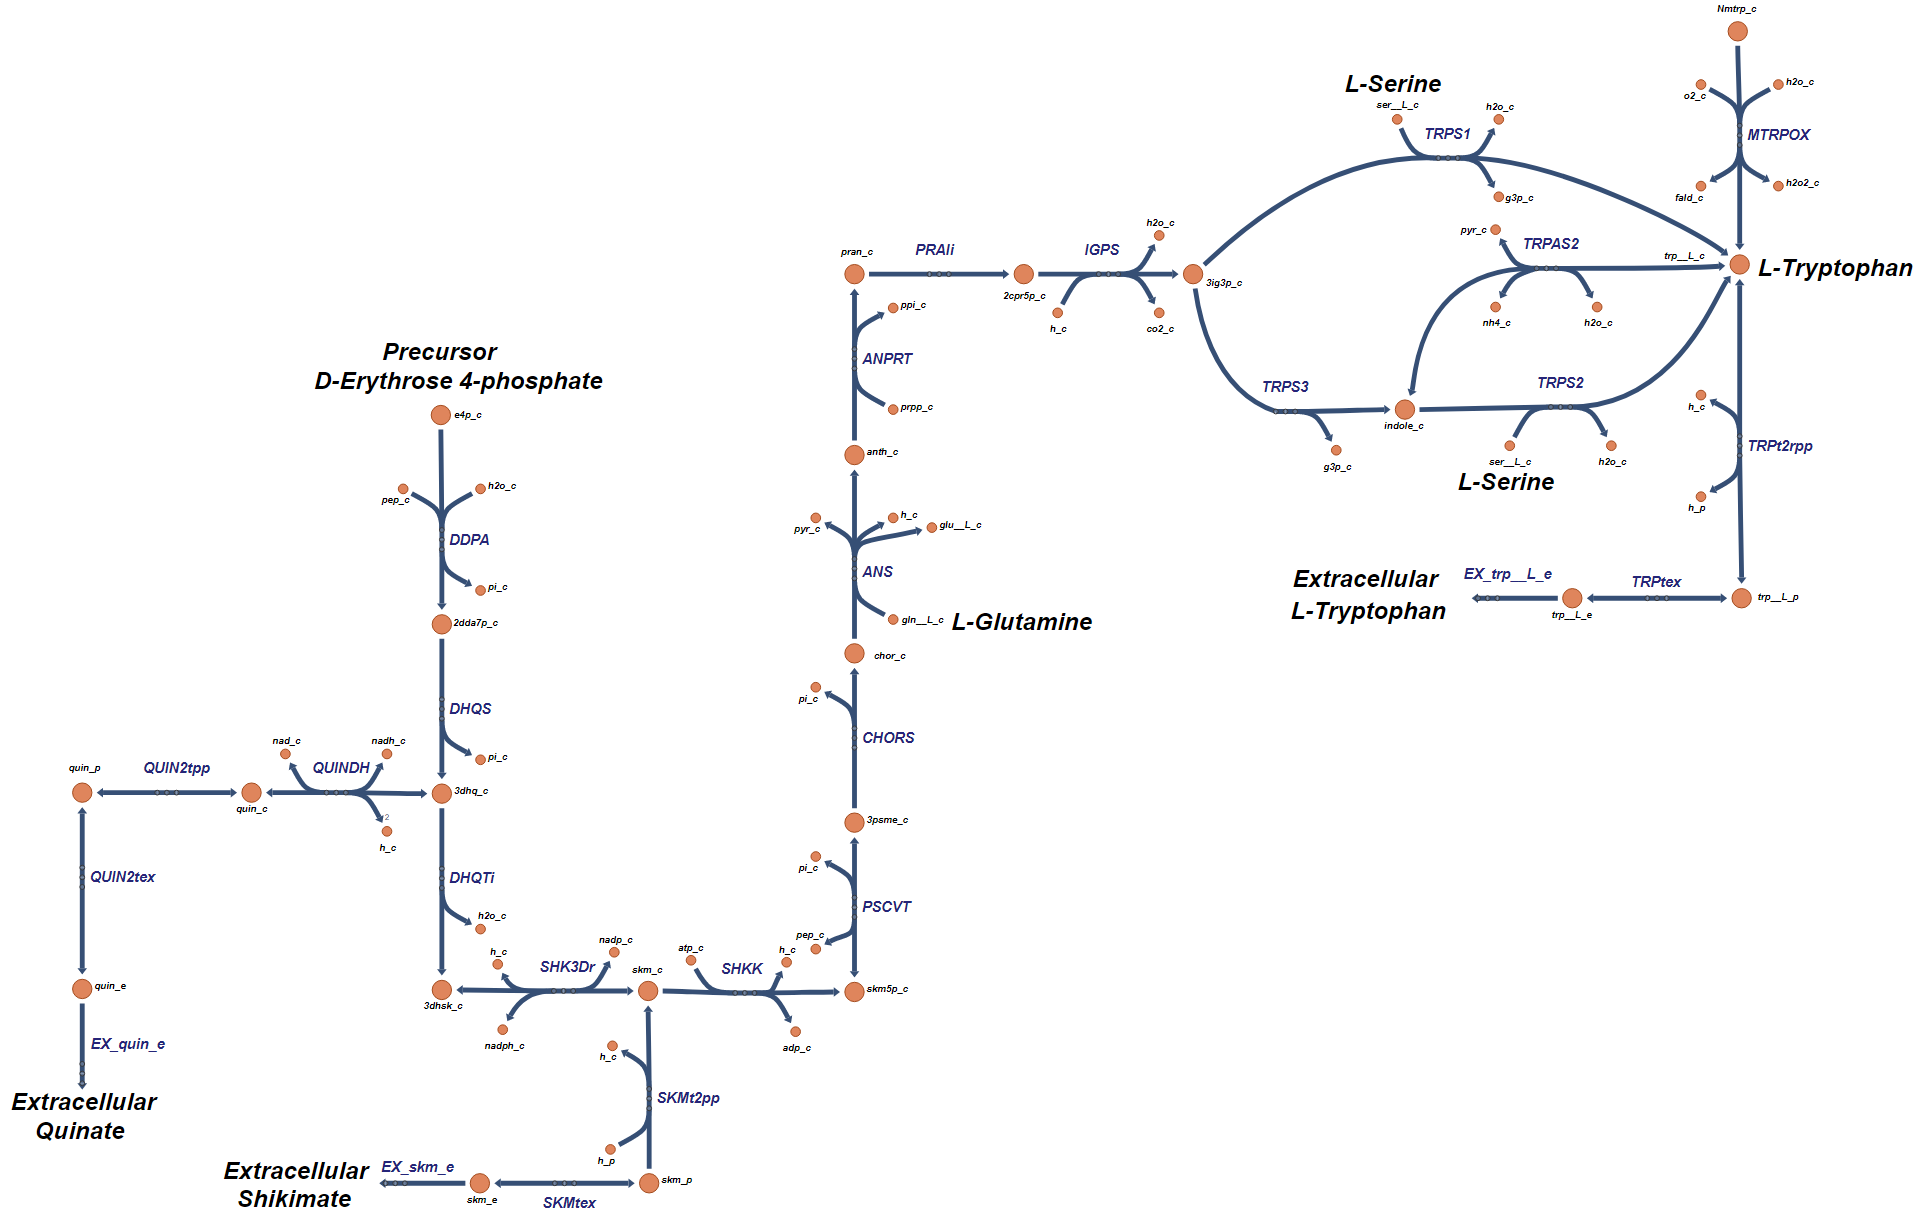

**Figure 5. **The biosynthesis pathway for L-tryptophan

In addition to the primary pathway ('DDPA', 'DHQS', 'DHQTi', 'SHK3Dr', 'SHKK', 'PSCVT', 'CHORS', 'ANS', 'ANPRT', 'PRAIi', 'IGPS', 'TRPS1', 'TRPS2', 'TRPS3', 'TRPAS2', and 'QUINDH'), it can be seen that there are two other potential pathways for the production of L-tryptophan. On the left of the figure there is an alternate pathway ('EX_quin_e', 'QUIN2tex', 'QUIN2tpp',  and 'QUINDH' ) that begins by the diffusion of quinate ('quin_e') into the periplasm ('quin_p') and then transported into the cytoplasm ('quin_c') where it adds to the pool of 3-Dehydroquinate ('3dhq_c') which is an intermediate step in the biosynthesis of L-tryptophan. Another pathway ('EX_skm_e', 'SKMtex', 'SKMt2pp') based on shikimate (skm_c') can be used to contribute to the front end of primary pathway involves the diffusion ('skm_e') and tranport of periplasmic shikimate ('skm_p').  The iJO1366 model includes the dead-end reaction ' MTRPOX' since there is no source of N-methyltryptophan oxidase ('NMtrp_c') within the model .  L-tryptophan can also be added to the cell through the proton powered transporter 'TRP2trpp' which bring periplasmic L-tryptophan ('trp__L_p') that is diffused into the cell via 'EX_trp__L_c' and 'TRPtex'.

Now let's explore the flux through this pathway under aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
tryptophanReactions = transpose({'DDPA','DHQS','DHQTi','SHK3Dr','SHKK','PSCVT','CHORS','ANS','ANPRT','PRAIi',...
    'IGPS', 'TRPS1', 'TRPS2', 'TRPS3', 'TRPAS2','EX_quin_e','QUIN2tex','QUIN2tpp','QUINDH','MTRPOX',...
    'EX_trp__L_e','TRPtex' });
[tmp,tryptophan_rxnID] = ismember(tryptophanReactions,model.rxns);
printLabeledData(tryptophanReactions, round(FBAsolution.x(tryptophan_rxnID),3))

DDPA	0.374	
DHQS	0.374	
DHQTi	0.374	
SHK3Dr	0.374	
SHKK	0.374	
PSCVT	0.374	
CHORS	0.374	
ANS	0.056	
ANPRT	0.056	
PRAIi	0.056	
IGPS	0.056	
TRPS1	0	
TRPS2	0	
TRPS3	0.056	
TRPAS2	-0.056	
EX_quin_e	0	
QUIN2tex	0	
QUIN2tpp	0	
QUINDH	0	
MTRPOX	-0	
EX_trp__L_e	0	
TRPtex	0	


Again we can see, that under aerobic conditions, it is the primary pathway that supports all the flux to production of L-tryptophan.

When a cell is producing a recombinant protein, it might be required to produce additional L-tryptophan for the desired bioproduct.  What is the maximum amount of L-tryptophan that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'trp__L_c');

DM_trp__L_c	trp__L_c 	->	


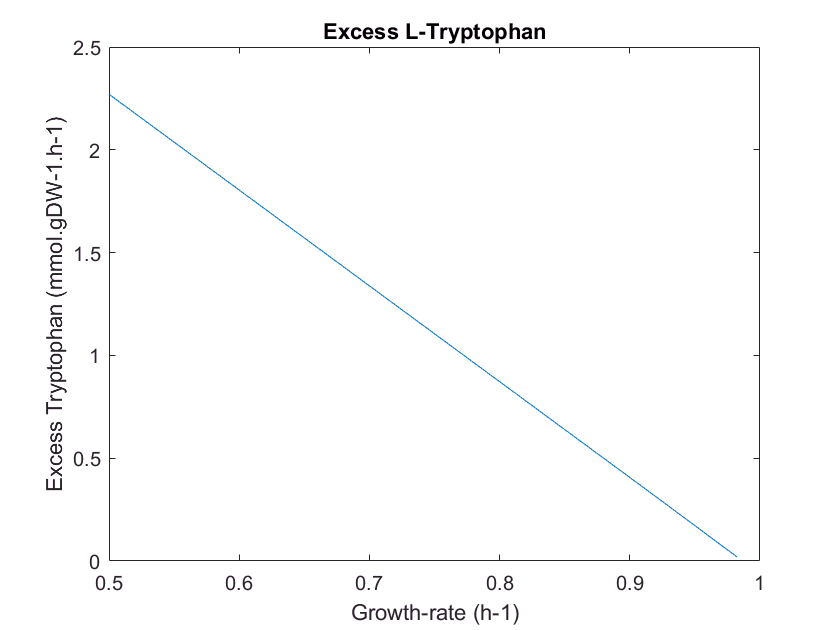

[tmp,tryptophan_MAX_rxnID] = ismember({'DM_trp__L_c'},model.rxns);
model = changeObjective(model,'DM_trp__L_c'); % Set the objective function
FBAsolution_tryptophan = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
% printLabeledData({'DM_trp__L_c'}, round(FBAsolution_tyrosine.x(tyrosine_MAX_rxnID),3))
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessTryptophan = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_tryptophan = optimizeCbModel(model,'max'); % Perform FBA
    excessTryptophan(i) = FBAsolution_tryptophan.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessTryptophan)
title('Excess L-Tryptophan'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess Tryptophan (mmol.gDW-1.h-1)');

**Figure 6. **The maximum amount of excess L-tryptophan that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-tryptophan increases the growth-rate will need to decrease. In this figure we can see that the excess L-tryptophan flux can increase from 0.0195 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 2.27 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-tryptophan flux beyond these levels will require uinsg the pathways that allow for the trasnport of L-tryptophan from the extracellular media. 

**4. L- Phenylalanine Biosynthesis**

As can be seen in the figure above the primary biosyntheis pathway for the production of L-phenylalanine begins with the precursor D-Erythrose 4-phosphate ('e4p_c') and includes the following reactions 'DDPA', 'DHQS', 'DHQTi', 'SHK3Dr', 'SHKK', 'PSCVT', 'CHORS', 'CHORM', 'PPNDH', 'PHETA1'. A figure showing all the reactions that can produce L-phenylalanine are shown below.

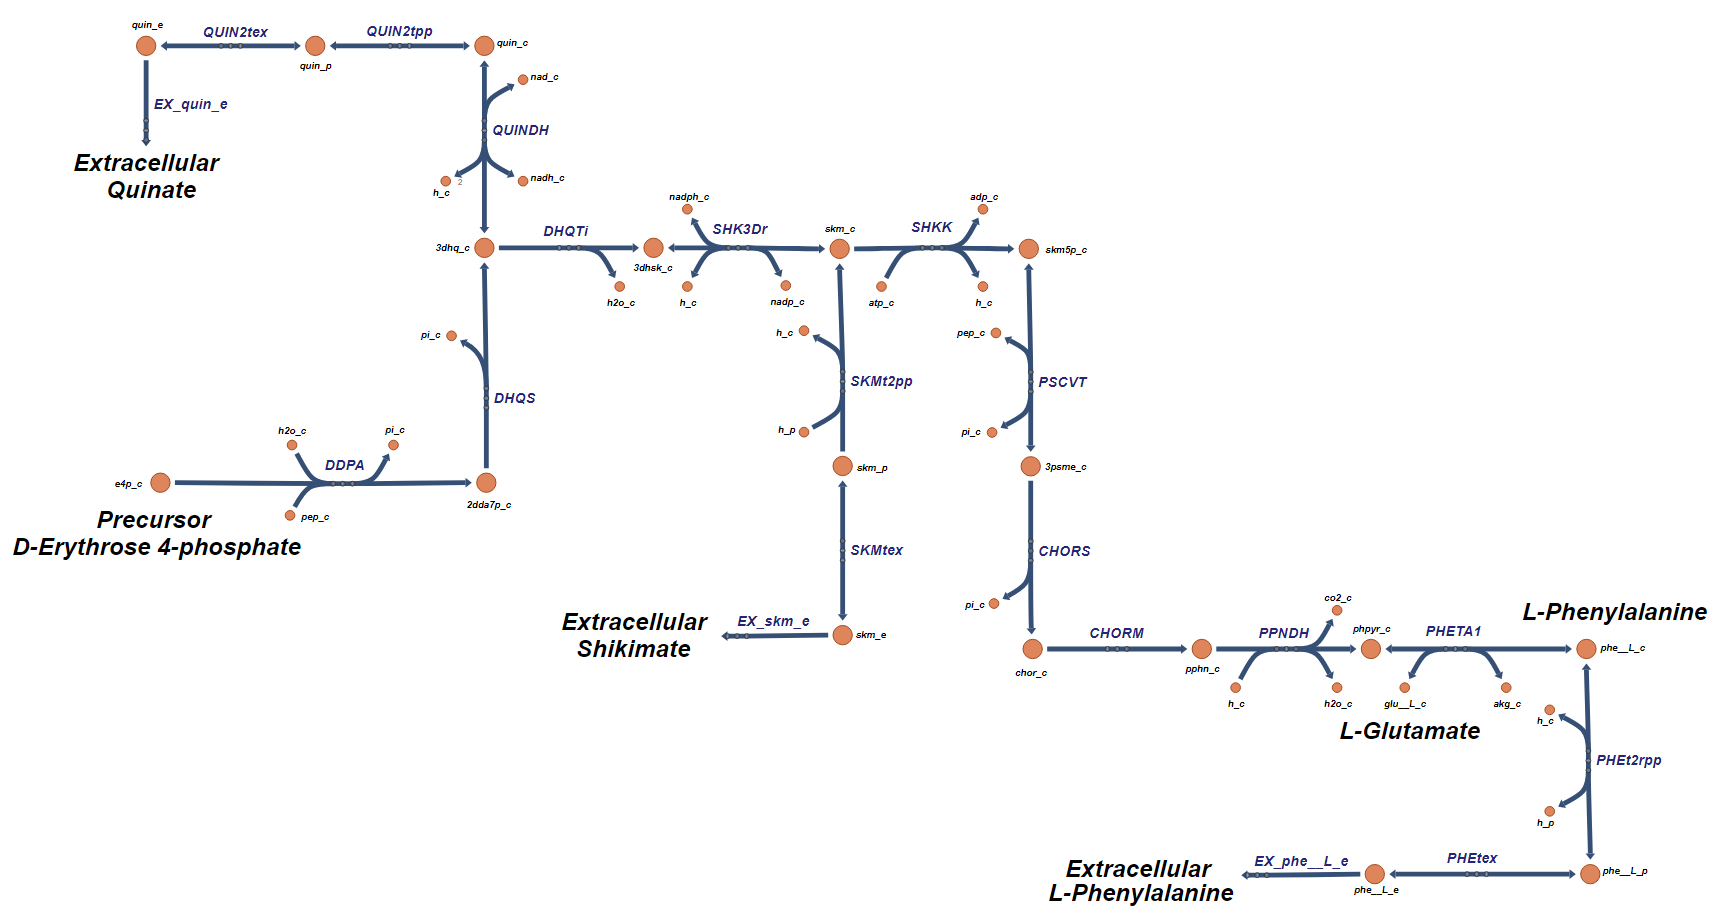

**Figure 7. **A network map showing all the pathways and reactions that can produce L-phenylalanine.

In addition to the primary pathway ('DDPA', 'DHQS', 'DHQTi', 'SHK3Dr', 'SHKK', 'PSCVT', 'CHORS', 'CHORM', 'PPNDH', 'PHETA1'), it can be seen that there are other potential pathways for the production of L-phenylalanine. On the top of the figure there is an alternate pathway ('EX_quin_e', 'QUIN2tex', 'QUIN2tpp',  and 'QUINDH' ) that begins by the diffusion of quinate ('quin_e') into the periplasm ('quin_p') and then transported into the cytoplasm ('quin_c') where it adds to the pool of 3-Dehydroquinate ('3dhq_c') which is an intermediate step in the biosynthesis of L-phenylalanine. Another pathway ('EX_skm_e', 'SKMtex', 'SKMt2pp') based on shikimate (skm_c') can be used to contribute to the front end of primary pathway involves the diffusion ('skm_e') and tranport of periplasmic shikimate ('skm_p'). L-phenylalanine can also be added to the cell through the proton powered transporter 'PHEt2rpp' which bring periplasmic L-phenylalanine ('phe__L_p') that is diffused into the cell via 'EX_phe__L_e' and 'PHEtex'.

Now let's explore the flux through this pathway under aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
phenylalanineReactions = transpose({'DDPA','DHQS','DHQTi','SHK3Dr','SHKK','PSCVT','CHORS','CHORM','PPNDH',...
    'PHETA1','EX_quin_e','QUIN2tex','QUIN2tpp','QUINDH','EX_phe__L_e','PHEtex','PHEt2rpp'});
[tmp,phenylalanine_rxnID] = ismember(phenylalanineReactions,model.rxns);
printLabeledData(phenylalanineReactions, round(FBAsolution.x(phenylalanine_rxnID),3))

DDPA	0.374	
DHQS	0.374	
DHQTi	0.374	
SHK3Dr	0.374	
SHKK	0.374	
PSCVT	0.374	
CHORS	0.374	
CHORM	0.318	
PPNDH	0.182	
PHETA1	-0.182	
EX_quin_e	0	
QUIN2tex	0	
QUIN2tpp	0	
QUINDH	0	
EX_phe__L_e	0	
PHEtex	0	
PHEt2rpp	0	


Again we can see, that under aerobic conditions, it is the primary pathway that supports all the flux to production of L-phenylalanine.

When a cell is producing a recombinant protein, it might be required to produce additional L-phenylalanine for the desired bioproduct.  What is the maximum amount of L-phenylalanine that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'phe__L_c');

DM_phe__L_c	phe__L_c 	->	


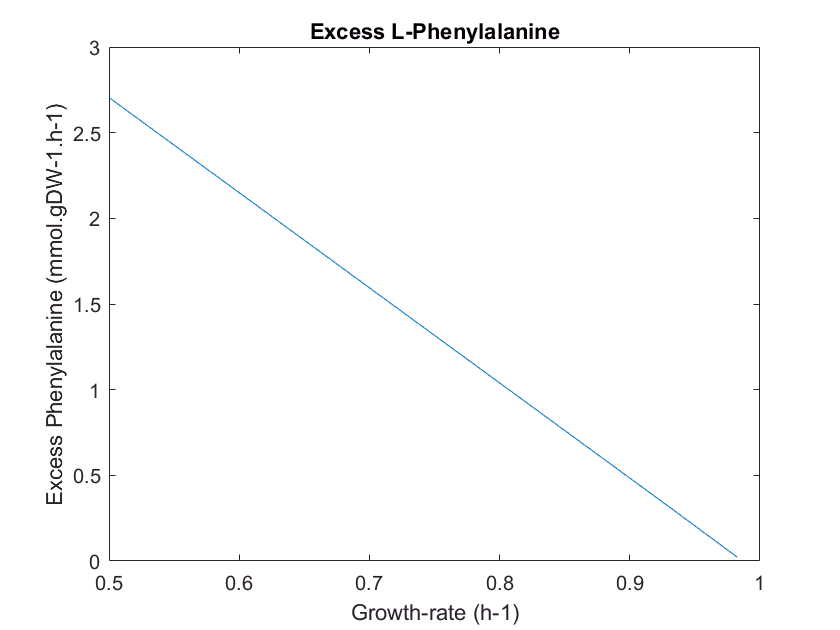

[tmp,phenylalanine_MAX_rxnID] = ismember({'DM_phe__L_c'},model.rxns);
model = changeObjective(model,'DM_phe__L_c'); % Set the objective function
FBAsolution_phenylalanine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
% printLabeledData({'DM_phe__L_c'}, round(FBAsolution_tyrosine.x(tyrosine_MAX_rxnID),3))
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessPhenylalanine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_phenylalanine = optimizeCbModel(model,'max'); % Perform FBA
    excessPhenylalanine(i) = FBAsolution_phenylalanine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessPhenylalanine)
title('Excess L-Phenylalanine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess Phenylalanine (mmol.gDW-1.h-1)');

**Figure 8. **A plot showing the maximum amount of L-phenylalanine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-phenylalanine increases the growth-rate will need to decrease. In this figure we can see that the excess L-phenylalanine flux can increase from 0.0233 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 2.705 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-phenylalanine flux beyond these levels will require using the pathways that allow for the trasnport of L-phenylalanine from the extracellular media. 

## 5. Aerobic vs Anaerobic Amino Acid Production

Now let's look at the total amount of flux that is created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

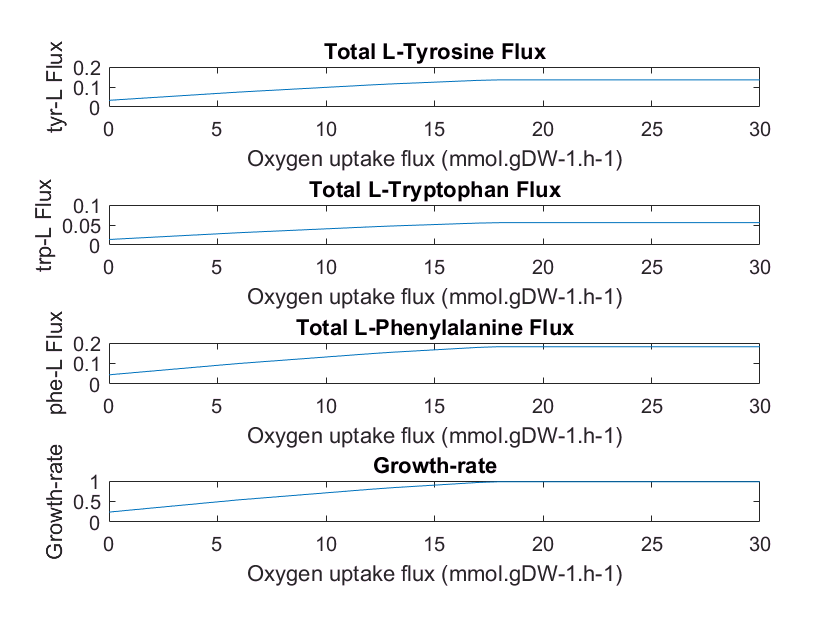

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
tyr_flux = [];
trp_flux = [];
phe_flux = [];
for k = 1:31
    model = changeRxnBounds(model,'EX_o2_e',-(k-1),'b'); % Set oxygen uptake
    FBAsolution = optimizeCbModel(model,'max'); % Perform FBA
    [P, C, vP, vC] = computeFluxSplits(model, {'tyr__L_c'}, FBAsolution.x);
    tyr_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'trp__L_c'}, FBAsolution.x);
    trp_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'phe__L_c'}, FBAsolution.x);
    phe_flux(k) = sum(vP);    
    growthRate(k) = FBAsolution.f;
end

figure(1)
oFlux = 0:30;
ax1 = subplot(4,1,1); % top subplot
ax2 = subplot(4,1,2); % middle subplot
ax3 = subplot(4,1,3); % bottom subplot
ax4 = subplot(4,1,4); % bottom subplot

plot(ax1,oFlux,tyr_flux)
title(ax1,'Total L-Tyrosine Flux'); 
xlabel(ax1,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax1,'tyr-L Flux');

plot(ax2,oFlux,trp_flux);
title(ax2,'Total L-Tryptophan Flux'); 
xlabel(ax2,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax2,'trp-L Flux'); 

plot(ax3,oFlux,phe_flux);
title(ax3,'Total L-Phenylalanine Flux'); 
xlabel(ax3,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax3,'phe-L Flux'); 

plot(ax4,oFlux,growthRate);
title(ax4,'Growth-rate'); 
xlabel(ax4,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax4,'Growth-rate'); 

**Figure 9.** A plot showing the total amount of flux that is can be created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

## 5. Conclusion

The purpose of this tutorial was to identify and review the structure and capabilities of the "Tyrosine, Tryptophan, and Phenylalanine Metabolism" subsystem of the *E.coli* iJO1366 model. It began with an overview of the complete subsystem. This was followed by more detailed descritpions of the individaul L-tyrosine, L-tryptophan, and L-phenylalanine biosynthesis pathways. It concluded with a simulation showing the maximum flux that each these amino acids can produce in a range from anaerobic to aerobic conditions.

## References

- Palsson, B. (2006). Systems biology : properties of reconstructed networks. Cambridge ; New York, Cambridge University Press.

- Orth, Fleming, and Palsson (2010), *EcoSal Chapter 10.2.1 - Reconstruction and Use of Microbial Metabolic Networks: the Core* Escherichia coli *Metabolic Model as an Educational Guide*  - [http://www.asmscience.org/content/journal/ecosalplus/10.1128/ecosalplus.10.2.1#backarticlefulltext](http://www.asmscience.org/content/journal/ecosalplus/10.1128/ecosalplus.10.2.1#backarticlefulltext)

- Zachary A. King, Andreas Dräger, Ali Ebrahim, Nikolaus Sonnenschein, Nathan E. Lewis, and Bernhard O. Palsson (2015) *Escher: A web application for building, sharing, and embedding data-rich visualizations of biological pathways*, PLOS Computational Biology 11(8):